# **ACM/IDS 104 - Problem Set 4 - MATLAB Problems**

*Before writing your MATLAB code, it is always good practice to get rid of any leftover variables and figures from previous scripts.*

clc; clear; close all;

## Problem 3 (10 points) Application of Least Squares to Data Fitting

The dataset $\texttt{carbig}$, a built-in MATLAB dataset, contains various characteristics for $m=406$ automobiles from the 1970s and 1980s. Let $x_1, \, x_2$ and $y$ be the $\texttt{Weight}$, $\texttt{Horsepower}$ and $\texttt{MPG (Miles Per Gallon)}$ respectively. Let us assume the following theoretical model for the data:


$$y = f(x_1, x_2) = \beta_0+\beta_1x_1+\beta_2x_2+\beta_3x_1x_2\,\,\,\,\,(\star)$$


Let $\beta^* = \left(\beta_0^*, \beta_1^*, \beta_2^*, \beta_3^*\right)^T$ denote the best fit to the data, i.e. the vector that minimizes the Euclidean norm of the residual vector $r = \left(r_1,\cdots,r_m\right)^T$, where:


$$r_i = y^{(i)}-f\left(x_1^{(i)}, x_2^{(i)}\right)$$


## Part (a) (5 points)

Derive the system of normal equations on $\beta^*$. Do this in your written-up solutions.

## Part (b) (5 points)

Find $\beta^*$ by solving the normal system numerically and plot the scatter plot of the data $\left\{\left(x_1^{(i)}, x_2^{(i)}, y^{(i)}\right)\right\}, i = 1\cdots m$, together with the fitted surface $y=f\left(x_1, x_2\right)$ given by $(\star)$.

To start, let us load the dataset, define our variables, and perform some necessary cleanup as there exist $\texttt{NaN}$ values. We do this for you :)

load carbig;
x1=Weight;
x2=Horsepower;
y=MPG;
clearvars -except x1 x2 y;
% Data cleaning
y=y(x1>0);
x2=x2(x1>0);
x1=x1(x1>0);

y=y(x2>0);
x1=x1(x2>0);
x2=x2(x2>0);

x1=x1(y>0);
x2=x2(y>0);
y=y(y>0);

Now, the dataset is ready for you to solve the normal system. Let us vizualize it. Drag the 3D plot around to get a better sense of the data.

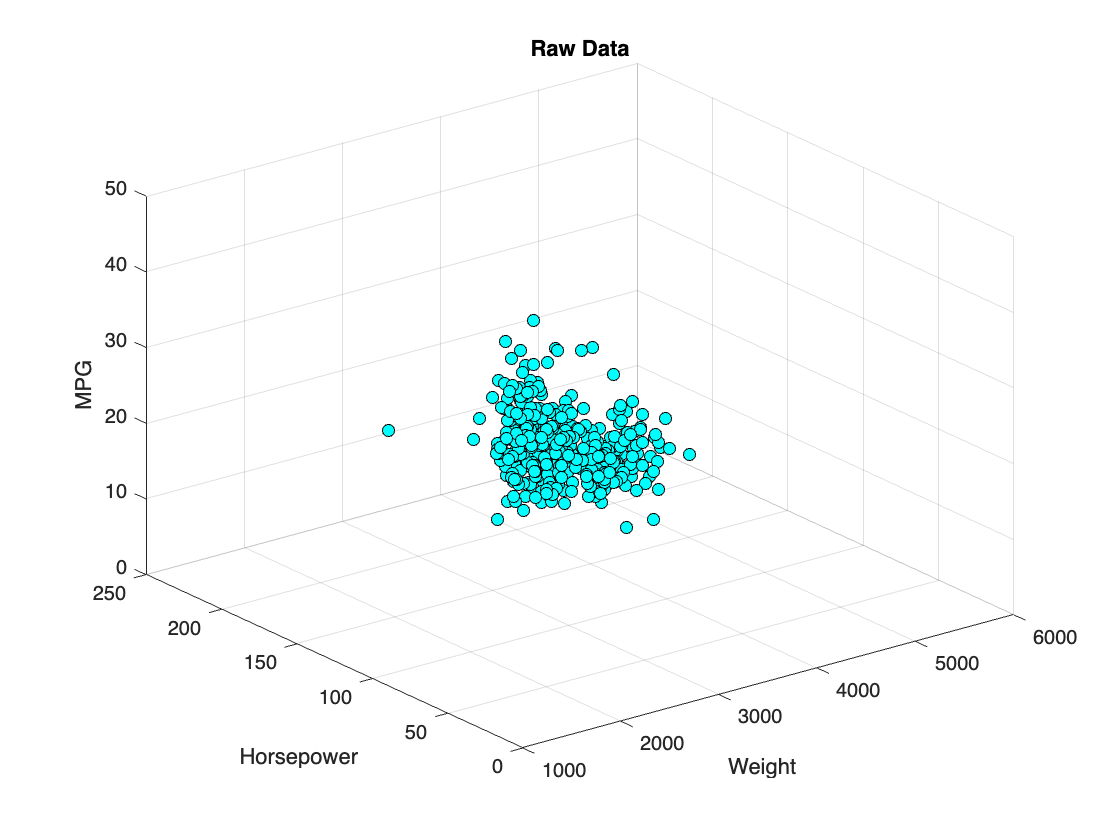

figure;
scatter3(x1,x2,y,'MarkerEdgeColor','k','MarkerFaceColor','c');
xlabel('Weight');
ylabel('Horsepower');
zlabel('MPG');
title('Raw Data');

Finally, let us find the best surface to fit the data. Remember, in MATLAB, when solving a system, backslash is your best friend. Use $\texttt{scatter3()}$ and $\texttt{fsurf()}$ when plotting.

%{
Build the matrix A
Solve for beta
%}
% A is an m by 4 matrix
m = size(y, 1);
A = zeros(m , 4);
for i=1:m
    A(i, :) = [1 x1(i, 1) x2(i,1) x1(i, 1)*x2(i,1)];
end

K = A' * A;
f = A' * y;

% solving for beta
beta = K \ f;
y_pred = A * beta;

%{
Plotting    
%}
figure;
scatter3(x1,x2,y,'MarkerEdgeColor','k','MarkerFaceColor','c');
hold on;
xlabel('Weight');
ylabel('Horsepower');
zlabel('f(x1, x2)');
[umin, ~] = min(x1);
[umax, ~] = max(x1);
[vmin, ~] = min(x2);
[vmax, ~] = max(x2);
func = @(x1,x2) [1, x1, x2, x1*x2]*beta;
fsurf(func, [umin umax vmin vmax])

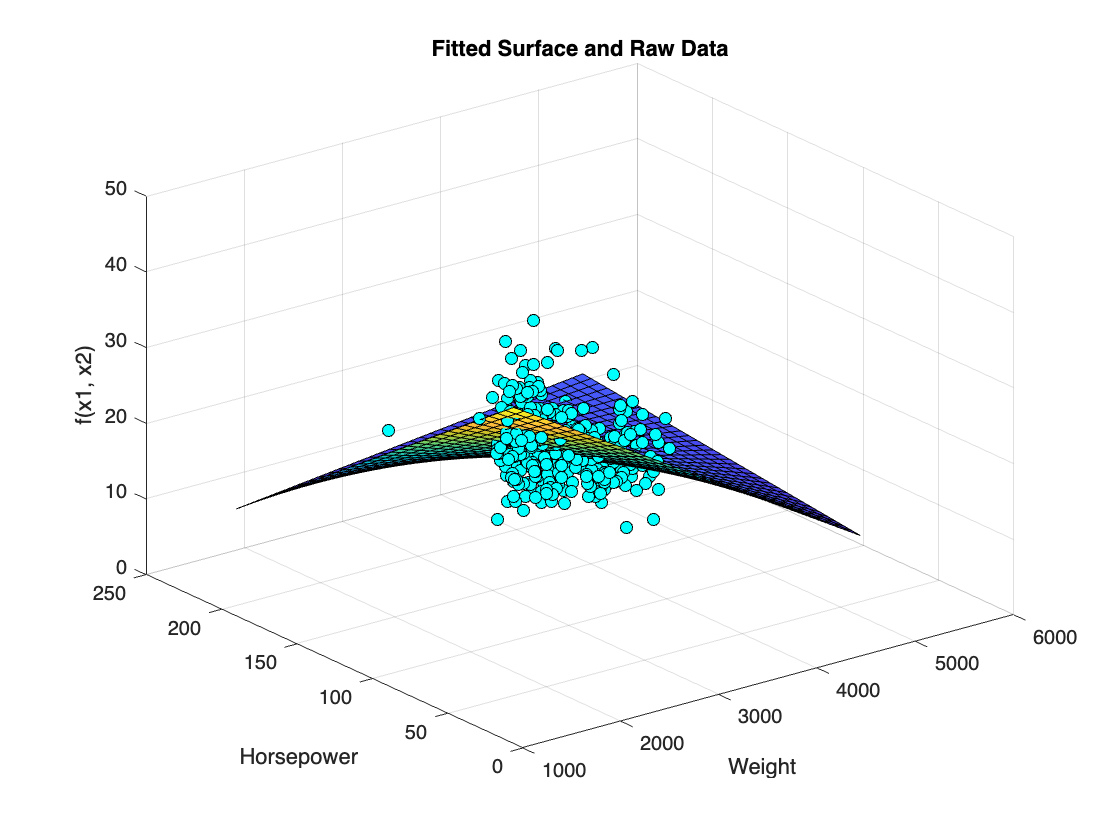

hold off;
title('Fitted Surface and Raw Data');

## Problem 4 (10 points) Polynomial Interpolation

Interpolating polynomials $p(x)$ are used for approximation of complex functions $g(x)$. Intuitively, the larger the degree of the interpolating polynomial, the more accurate the approximation $g(x)\approx p(x),x\in [a,b]$. Generally, this is not true (as you will see in this problem). High degree interpolating polynomials often behave badly, especially near the ends of the interval $[a,b]$. In practice, piecewise cubic splines are often used instead of high degree polynomials.

Suppose we want to approximate the function:


$$g(x) = \frac{\cos x}{\cosh x},\,\,x\in[-a,a]$$


using $n$ points equally spaced between $-a$ and $a$. Find the interpolating polynomials and plot them versus the function $g(x)$ for $a = 1, 5$ and $n = 3, 5, 10, 15$. In your plot, show also the data points used for interpolation. The code should produce a single figure with 8 subplots.

Useful MATLAB functions for this problem:


$$\texttt{linspace(), fplot(), polyval(), polyfit()}$$


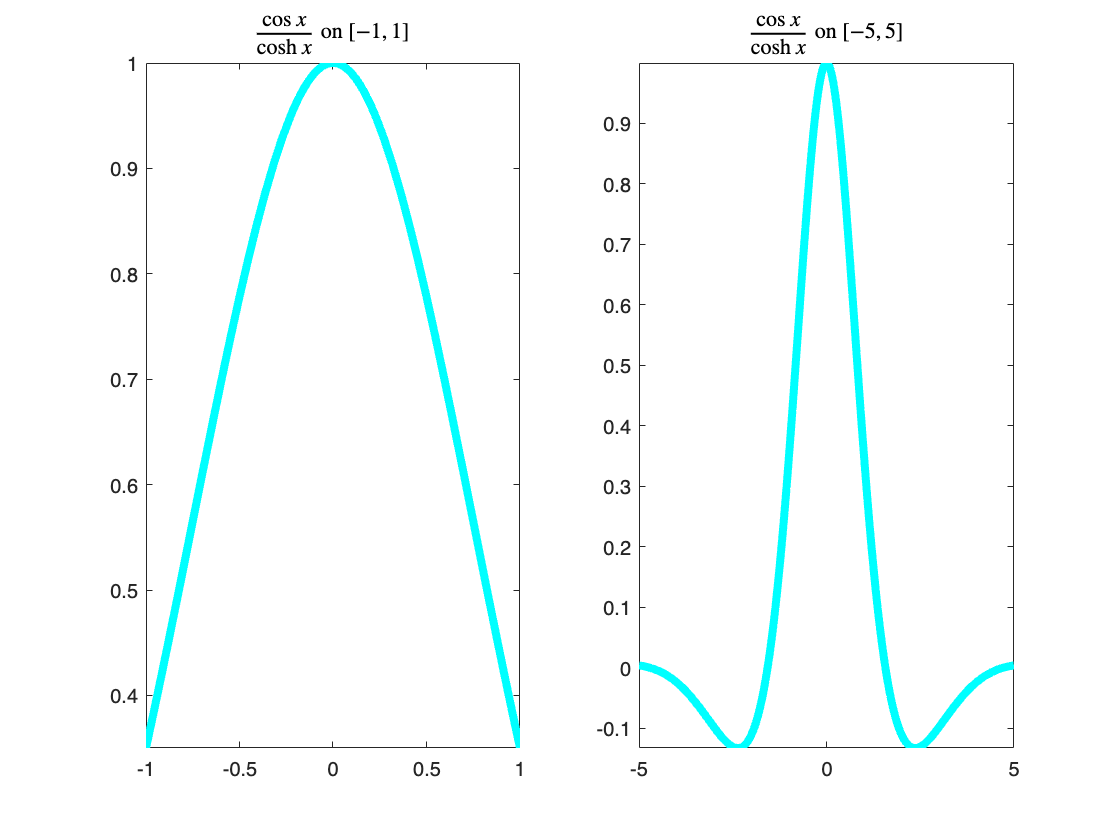

%{Let us start by doing some setup
%}
g = @(x) cos(x) ./ cosh(x); % you can define functions like this
a = [1, 5]; % setting interval values
n = [3, 5, 10, 15]; % setting the number of points
sub = 1; % setting the subplot index

%{
Let us see how g(x) looks like on both intervals
%}
figure;
subplot(1, 2, 1);
fplot(g, [-a(1), a(1)], "-c", "lineWidth", 4);
title("$\frac{\cos{x}}{\cosh{x}}$ on $[-1, 1]$","Interpreter","latex");
hold on
subplot(1, 2, 2);
fplot(g, [-a(2), a(2)], "-c", "lineWidth", 4);
title("$\frac{\cos{x}}{\cosh{x}}$ on $[-5, 5]$","Interpreter","latex");

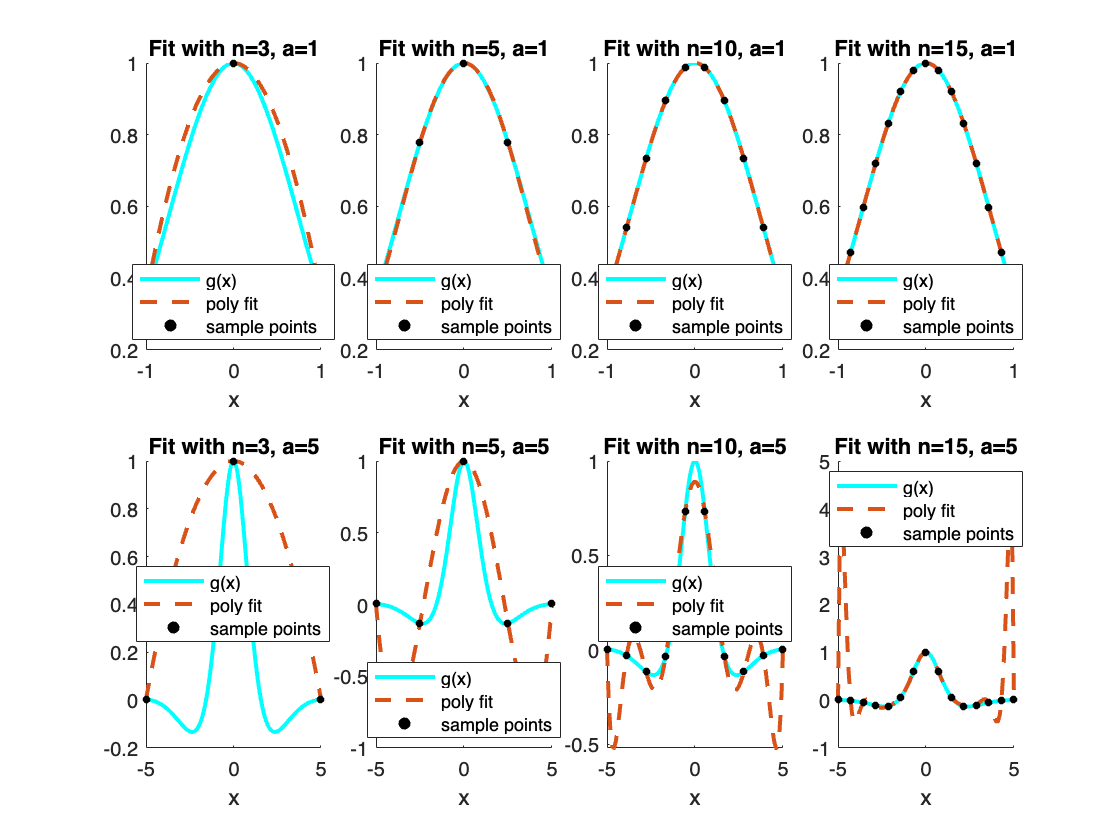


%{
Complete the nested for-loops
%}
plot_pos = 1;
figure;
for ival = a
    for degree = n-1
        %{
        Select degree+1 points in the interval
        Evaluate g(x) on these points
        Find the polynomial coefficients
        %}
        points = linspace(-ival, ival, degree + 1);
        g_eval = g(points);
        coeffs = polyfit(points, g_eval, degree);
        
        
        %{ 
        PLOTTING
        Plot g(x), the sampled points and interpolating polynomial
        Please use different colors and linestyles
        %}
        subplot(2,4, plot_pos);
        hold on
        fplot(g, [-ival, ival], "-c", "lineWidth", 2);
        title(compose("Fit with n=%d, a=%d", degree+1, ival));
        xlabel("x");
        more_points = linspace(-ival, ival, 100);
        plot(more_points, polyval(coeffs, more_points), "--", "lineWidth", 2);
        scatter(points, g_eval, 15, 'k', "filled");
        legend("g(x)", "poly fit", "sample points", "location", "best");
        plot_pos = plot_pos + 1;
        
    end
end

## Problem 5 (10 points) Stability of the Gram-Schmidt Algorithm

The classical Gram-Schmidt algorithm is numerically unstable. This means that, when implemented on a computer, the round-off errors can cause the output vectors to be significantly non-orthogonal. To explore the issue, perform the following computations for each $n = 10, 20, 30,\cdots, 100$:

- Create the Hilbert matrix $H_n$ of size $n$ (using $\texttt{hilb(n)}$) and consider the columns $h_1,\cdots,h_n$ as a basis of $\mathbb{R}^n$. The matrix $H_n$ is non-singular, and thus its columns indeed form a basis, but it is very close to singular (i.e. its columns are close to being linearly dependent), and this leads to numerical problems.

- Implement the basic Gram-Schmidt algorithm to construct an orthogonal basis $\{v_1,\cdots,v_n\}$ of $\mathbb{R}^n$ from $h_1,\cdots,h_n$. Please don't use any advanced built-in function for orthogonalization (such as $\texttt{orthog()}$) just basic matrix operations. At the end of the process normalize your vectors so that the basis is orthonormal.

- If vectors $v_1,\cdots,v_n$ obtained in (2) are orthonormal, then $V = [v_1,\cdots,v_n]$ must be orthogonal. As a measure of orthogonality, compute the infinite norm $\delta_V(n) = ||I_n-V^TV||_{\infty}$, which is a matrix norm (use $\texttt{norm(A, Inf)}$). The closer $\delta_V(n)$ is to zero, the closer the columns of $V$ are to being orthogonal.

- Repeat (2) and (3) to construct an orthonormal basis $\{u_1,\cdots,u_n\}$ using the modified Gram-Schmidt algorithm (which is numerically more stable) described in lecture 9 (page 46), and compute $\delta_U(n)$.

- To compare the basic and modified Gram-Schmidt algorithms, plot $\delta_V(n)$ and $\delta_U(n)$ versus $n$.

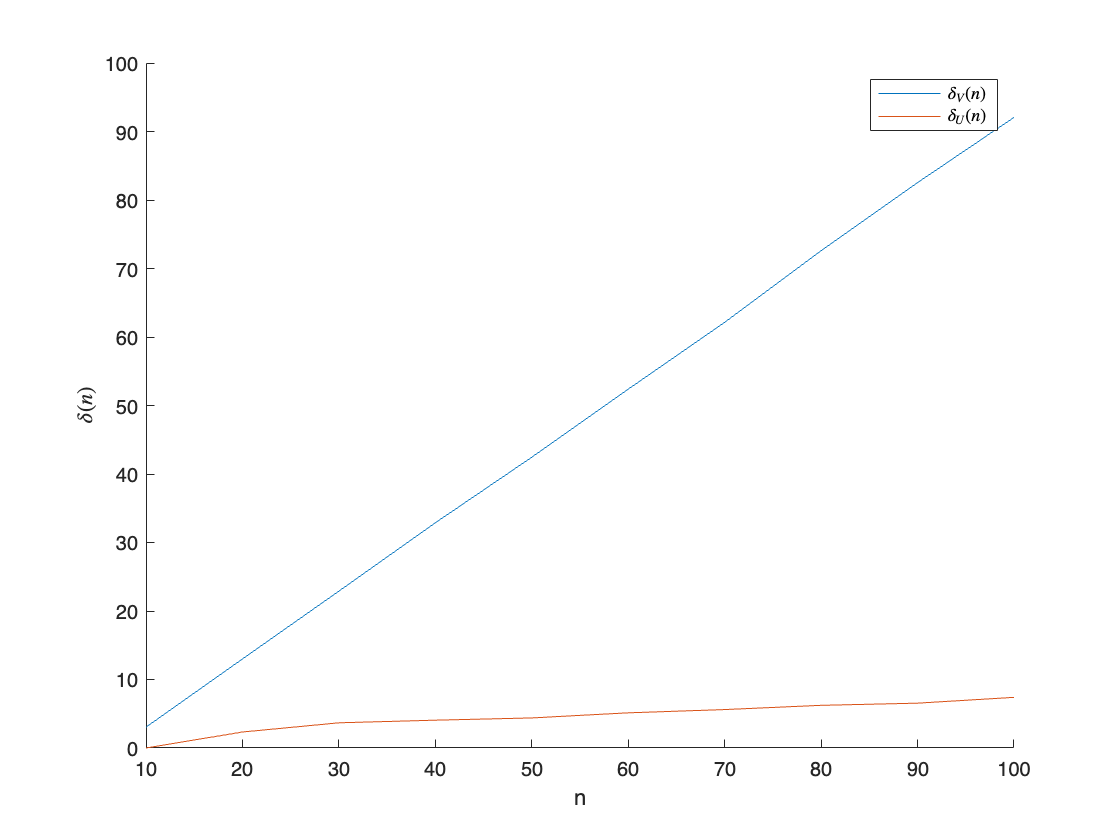

%{
Complete the following for-loop following (1)-(4)
%}
clc; clear;
delta_v = zeros(1, 10);
delta_u = zeros(1, 10);
for n=10:10:100
    %step 1
    H = hilb(n);
 
    %step 2, Gram-Schmidt (unstable version)
    basis = zeros(n, n);
    basis(:,1) = H(:,1);
    for k = 2:n
        wk = H(:,k);
        sum = zeros(n, 1);
        for i = 1:(k-1)
            vi = basis(:,i);
            sum = sum + dot(wk, vi) * vi / (norm(vi) * norm(vi));
        end
        basis(:, k) = wk - sum;
    end

    %step 3, Gram-Schmidt (unstable version)
    %normalize all vector
    for i = 1:n
        basis(:,i) = basis(:,i) / norm(basis(:,i));
    end

    A = eye(n) - basis' * basis;
    measure_unstable = norm(A, Inf);
    index = cast(n/10, "uint8");
    delta_v(1, index ) = measure_unstable;


    %step 2, Gram-Schmidt (stable version)
    basis = zeros(n, n);
    for j = 1:n
        basis(:, j) = H(:,j)/norm(H(:,j));
        for k = (j+1):n
            H(:,k) = H(:,k) - dot(H(:,k),basis(:, j)) * basis(:, j);
        end
    end

    %step 3, vectors are already normalized
    A = eye(n) - basis' * basis;
    measure_stable = norm(A, Inf);
    index = cast(n/10, "uint8");
    delta_u(1, index ) = measure_stable;
    
end
%{
Visualize the comparison as specified in (5)
%}
figure;
hold on
plot(10:10:100, delta_v);
plot(10:10:100, delta_u);

legend('$\delta_V (n)$','$\delta_U (n)$', 'Interpreter','latex');
xlabel("n");
ylabel("$\delta (n)$","Interpreter","latex");

